# PCA Data Exploration and Figures

## Extract PlasticityExperiment coordinate data

% Preliminaries
PlasticityVarDir = 'PlasticityExperiment';
PlasticityExpName = 'naive';

% Create/update PlasticityExperiment
PE = PlasticityExperiment(PlasticityExpName);
PE.UpdateDir(PlasticityVarDir);

% Load/Parse PlasticityExperiment
Load(PE)

Loading: [----------]


Parse(PE)

(1/3) Concatenating STDP matrices...done
(2/3) Performing PCA...done
(3/3) Saving output...done


% Retrieve PCA coordinates
coords = PE.Coord;

## Extract ThresholdData for each PlasticityExperiment

% Preliminaries
ThresholdVarDir = 'ThresholdExperiment/STDP';

% List of all ThresholdExperiments for PlastcitiyExperiment STDP data
ExpNames = dir([ThresholdExperiment('').param.vardir,ThresholdVarDir]);
ExpNames = ExpNames(arrayfun(@(f)contains(f.name,'PlasticityExperiment-naive'),ExpNames));

% Sort in numerical order (c.f. character/alphabetical order)
[ExpNums,idx] = sort(arrayfun(@(s)str2num(s.name(28:end)),ExpNames));
ExpNames = ExpNames(idx);

% Create array of ThresholdExperiments
TE = arrayfun(@(f)ThresholdExperiment(f.name),ExpNames);
arrayfun(@(te)te.UpdateDir(ThresholdVarDir),TE);

% Load and trim array (keep experiments with >0 Simulations)
arrayfun(@(te)Load(te),TE);
idx = arrayfun(@(te)~isempty(te.S),TE);
TE = TE(idx);
ExpNums = ExpNums(idx);

% Extract thresholds
thresholds = arrayfun(@(te)Threshold(te),TE);


## Best fit threshold plane

% Pair down coordinates to only those with defined threshold values
[cX,cY] = deal(coords(ExpNums,1),coords(ExpNums,2));

% Define a linear plane fit
f = fittype('poly11');

% Curve-fitting
[F,gof] = fit([cX,cY],thresholds,f);

### Plot best fit plane in 3D

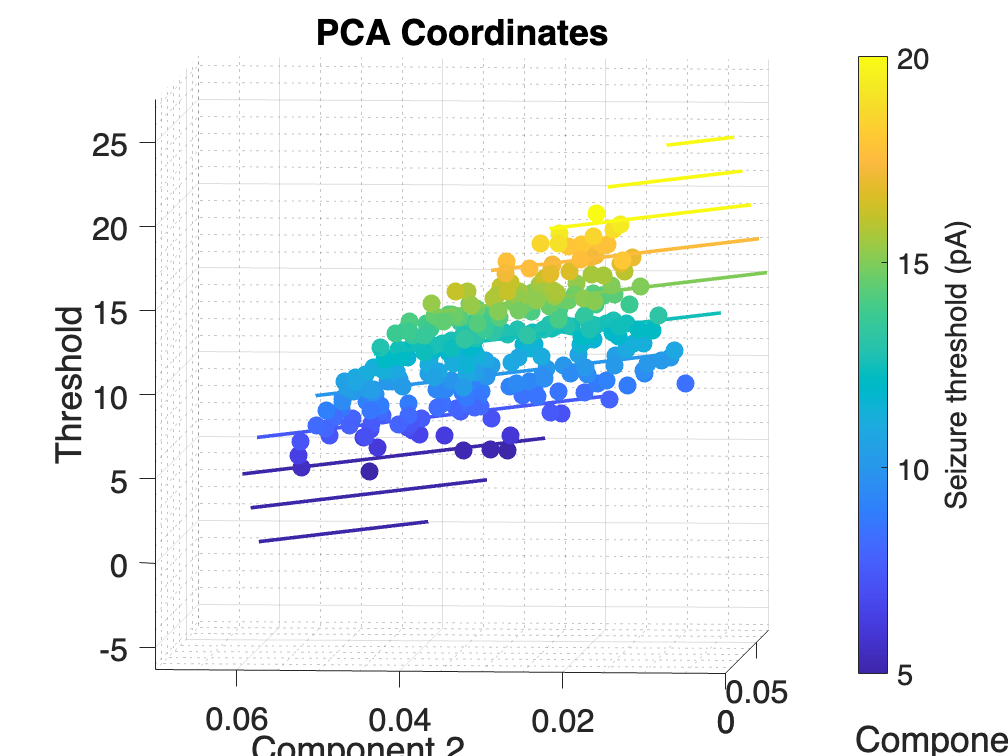

% Meshgrid for prediction sites
[mX,mY] = meshgrid([0:0.005:0.07],[0:0.005:0.06]);

% Generate the plot
figure

% Compute colors for thresholds
cb = parula(256); % colorbar of interest
cbi = [5:15/255:20].'; % digitize colorbar by threshold
tc = cb(dsearchn(cbi,thresholds),:); % threshold colors

% Plot color markers
scatter3(coords(ExpNums,1),coords(ExpNums,2),thresholds,100,tc,'filled')
hold on
xlim([0 0.07])
ylim([0 0.07])
contour3(mX,mY,F(mX,mY),0:2.5:30,'LineWidth',2)

% Grid limits
a = gca;
grid on
grid(a,'minor')
axis square

% Labels
a.XLabel.String = 'Component 1';
a.YLabel.String = 'Component 2';
a.ZLabel.String = 'Threshold';
a.Title.String = 'PCA Coordinates';
a.FontSize = 18;

% Colorbar
cbr = colorbar;
caxis([5 20])
cbr.Label.String = 'Seizure threshold (pA)';

% Quiver plot
[xp,yp] = deal(a.XLim(1) + (a.XLim(2) - a.XLim(1))./2 , a.YLim(1) + (a.YLim(2) - a.YLim(1))./2);
[fx,fy] = differentiate(F,[xp yp]);
scale = 0.01;
dx = sign(fx).*scale.*cos(atan(fy./fx));
dy = sign(fy).*scale.*sin(atan(fy./fx));
% quiver3( xp, yp, F(xp,yp), dx, dy, F(xp+dx,yp+dy) - F(xp,yp),1,'k','MaxHeadSize',0.02,'LineWidth', 4 );


gifFile = '~/Desktop/PlaneFit.gif';
view([-85.7 4.3])
exportgraphics(a, gifFile);
for i = 1:120
   camorbit(3,0,'data',[0 0 1])
   drawnow   
   exportgraphics(a, gifFile,Append=true);
end

### Plot best fit plane in 2D with motion vector

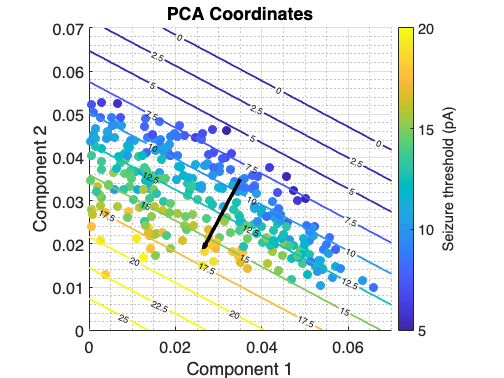

% Meshgrid for prediction sites
[mX,mY] = meshgrid([0:0.005:0.07],[0:0.005:0.07]);

% Generate the plot
figure

% Compute colors for thresholds
cb = parula(256); % colorbar of interest
cbi = [5:15/255:20].'; % digitize colorbar by threshold
tc = cb(dsearchn(cbi,thresholds),:); % threshold colors

% Plot color markers
scatter(coords(ExpNums,1),coords(ExpNums,2),100,tc,'filled')
a = gca;
xlim([0 0.07])
ylim([0 0.07])
hold on
contour(mX,mY,F(mX,mY),0:5:30,'LineWidth',2,'ShowText','on')

% Quiver plot
[xp,yp] = deal(a.XLim(1) + (a.XLim(2) - a.XLim(1))./2 , a.YLim(1) + (a.YLim(2) - a.YLim(1))./2);
[fx,fy] = differentiate(F,[xp yp]);
scale = 0.02;
dx = sign(fx).*scale.*cos(atan(fy./fx));
dy = sign(fy).*scale.*sin(atan(fy./fx));


quiver( xp, yp, dx, dy, 'k', 'LineWidth', 4 );

% Grid limits
a = gca;
grid on
grid(a,'minor')
axis square

% Labels
a.XLabel.String = 'Component 1';
a.YLabel.String = 'Component 2';
a.ZLabel.String = 'Threshold';
a.Title.String = 'PCA Coordinates';
a.FontSize = 18;

% Colorbar
cbr = colorbar;
caxis([5 20])
cbr.Label.String = 'Seizure threshold (pA)';

## Plot predicted threshold values (per model) against error

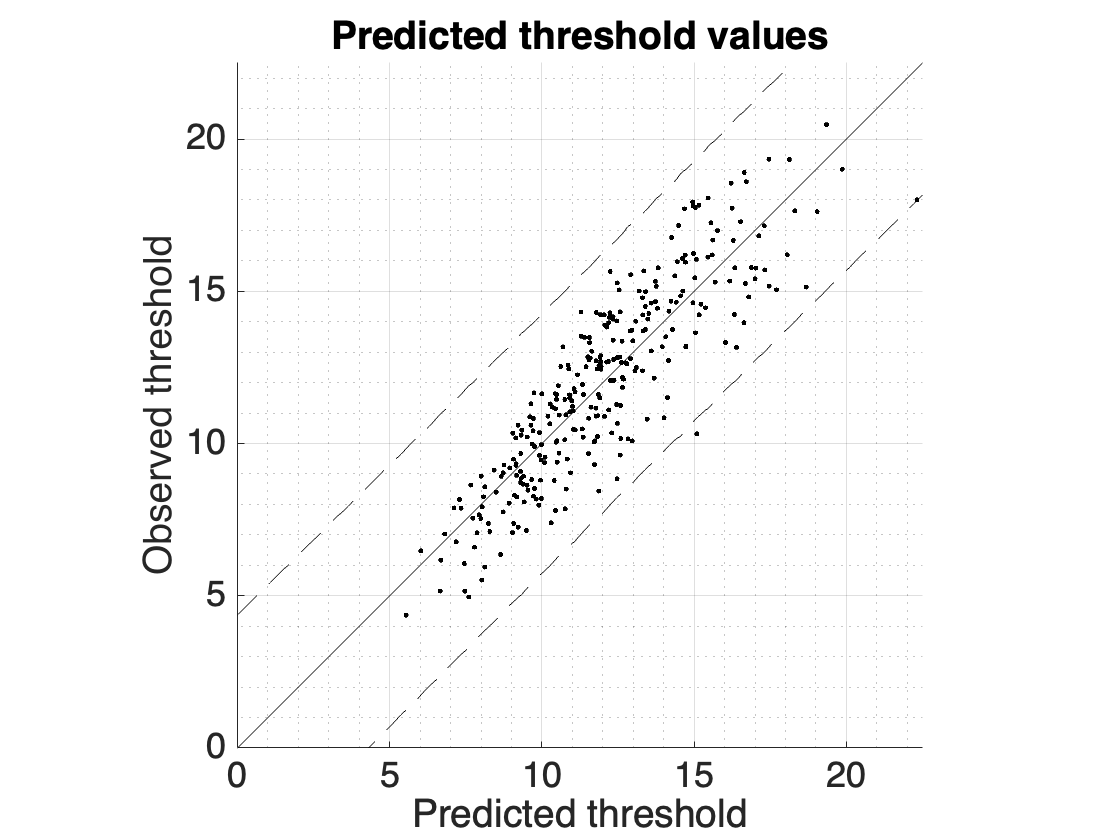

% Meshgrid for prediction sites
[mX,mY] = meshgrid([0:0.005:0.07],[0:0.005:0.06]);

% Compute predictions and associated error intervals
predictions = F(mX(:),mY(:));
predictionIntervals = predint(F,[mX(:) mY(:)],0.95,'observation','on');

% Create figure and plot
f = figure;
hold on;
[~,j] = unique(predictions);
plot(predictions(j),predictionIntervals(j,1),'k--');
plot(predictions(j),predictionIntervals(j,2),'k--');

plot(predictions,predictions,'k-');
plot(F(cX,cY),thresholds,'k.')
% Formatting options
a = gca;
grid on
grid('minor')
axis square
ylim([0 22.5]);
xlim([0 22.5]);
title('Predicted threshold values');
xlabel('Predicted threshold')
ylabel('Observed threshold');
a = gca;
a.FontSize = 18;

figure
delta = F(cX,cY)-thresholds;
histfit(delta,[],'normal')
pd = fitdist(delta,'normal')

pd =   NormalDistribution

  Normal distribution
       mu = 7.20575e-15   [-0.170345, 0.170345]
    sigma =     1.50179   [1.39064, 1.6324]


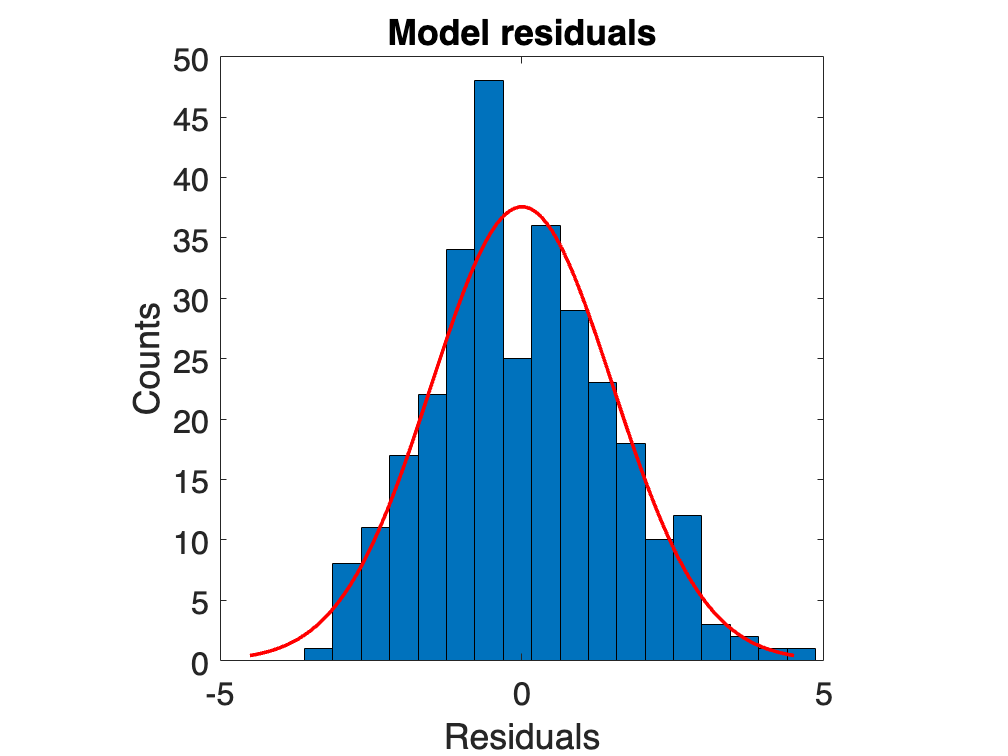

title('Model residuals');
xlabel('Residuals')
ylabel('Counts');
a = gca;
a.FontSize = 18;
axis square

[h,p] = kstest(delta,'CDF',pd)

h = logical
   0


p = 0.2233

## Plot the motion matrix

This is simply the derivative, and the plan is to increase seizure threshold

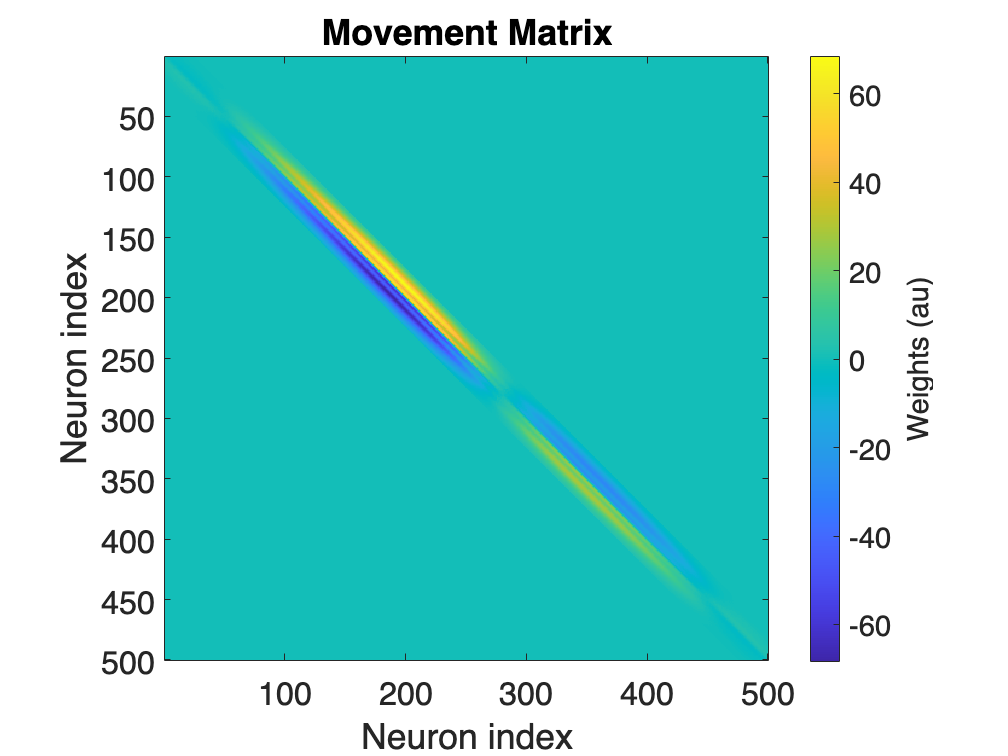

% Compute motion matrix
M = F.p10.*PE.pca.s(:,:,1) + F.p01.*PE.pca.s(:,:,2);
M = reshape(M,[PE.param(1).n PE.param(1).n]);
figure
imagesc(M)

a = gca;
a.XLabel.String = 'Neuron index';
a.YLabel.String = 'Neuron index';
a.FontSize = 18; axis square;
cb = colorbar; cb.Label.String = 'Weights (au)';
a.Title.String = ['Movement Matrix'];

## Plot the classic overlay plot

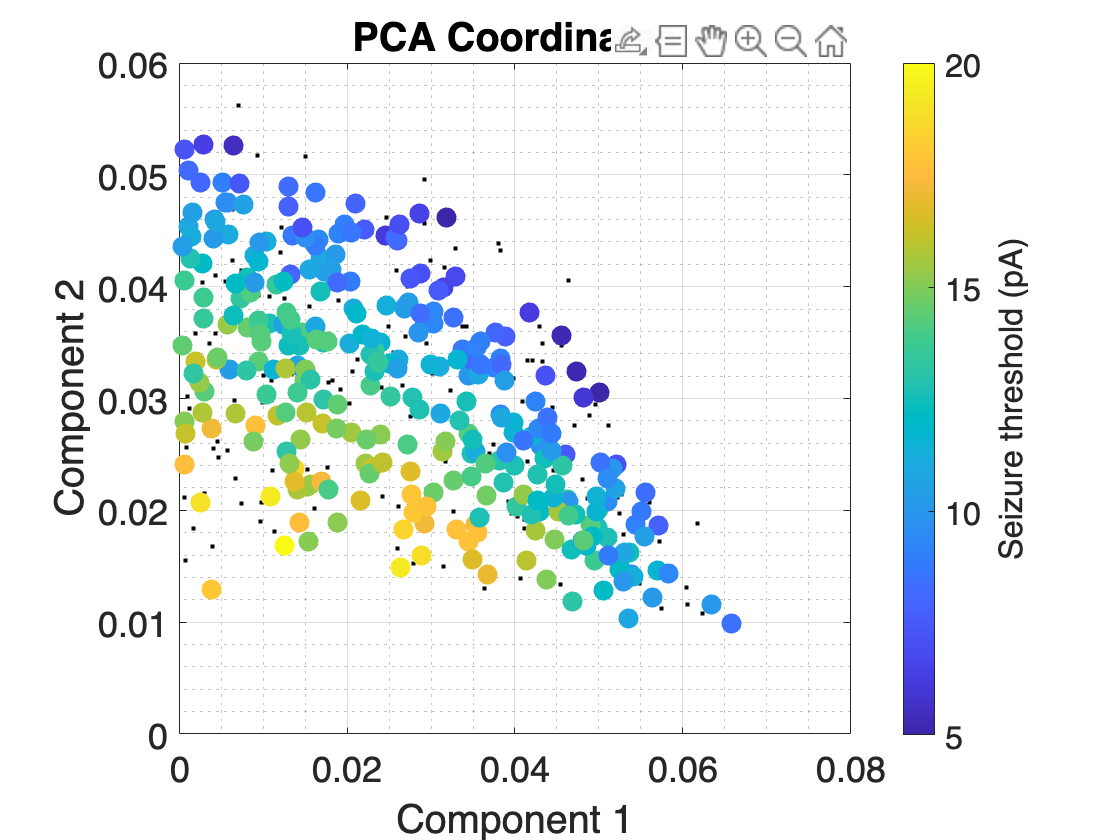

%% Plot threshold overlay on PCA component plot
% Generate figure and background
f = figure;
plot(coords(:,1),coords(:,2),'k.')
hold on

% Grid limits
a = gca;
grid on
grid(a,'minor')
axis square

% Labels
a.XLabel.String = 'Component 1';
a.YLabel.String = 'Component 2';
a.Title.String = 'PCA Coordinates';
a.FontSize = 18;

% Compute colors for thresholds
cb = parula(256); % colorbar of interest
cbi = [5:15/255:20].'; % digitize colorbar by threshold
tc = cb(dsearchn(cbi,thresholds),:); % threshold colors

% Plot color markers
scatter(coords(ExpNums,1),coords(ExpNums,2),100,tc,'filled')

% Colorbar
cbr = colorbar;
caxis([5 20])
cbr.Label.String = 'Seizure threshold (pA)';

## Plot first two components

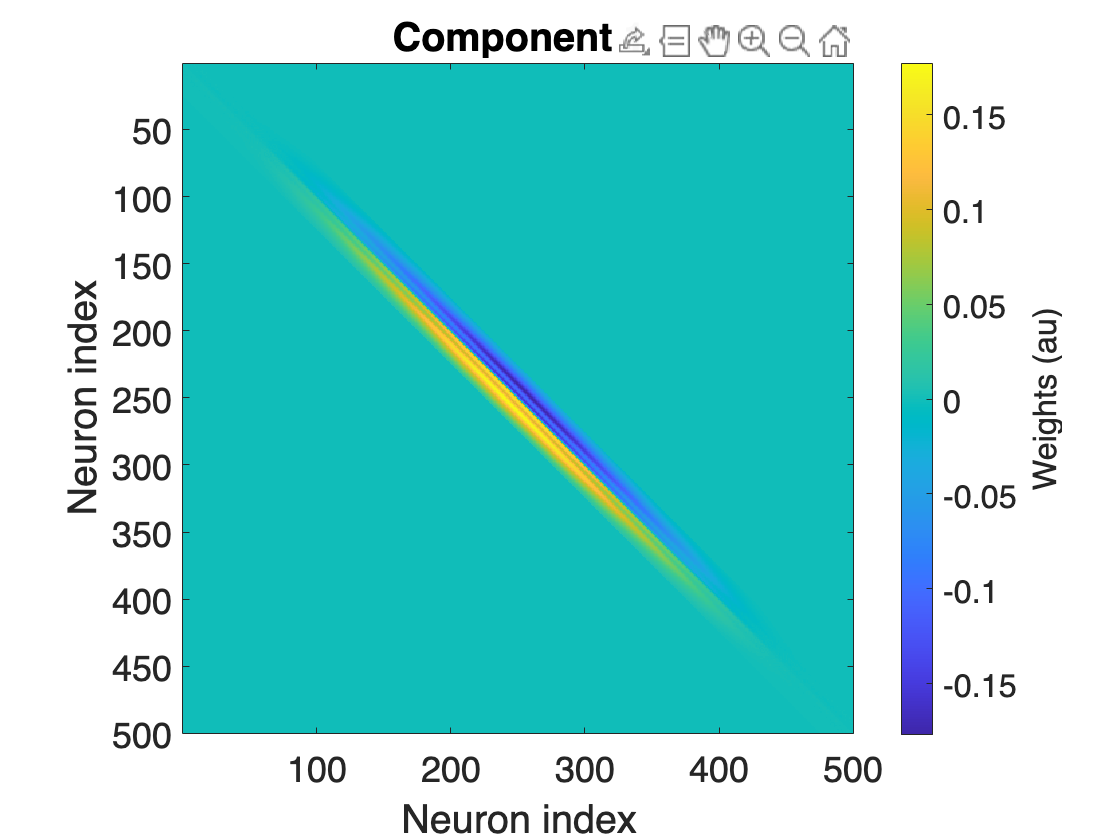

% Plot Component 1
f = figure; 
imagesc(PE.pca.s(:,:,1)); 
a = gca;
a.XLabel.String = 'Neuron index';
a.YLabel.String = 'Neuron index';
a.FontSize = 18; axis square;
cb = colorbar; cb.Label.String = 'Weights (au)';
a.Title.String = 'Component 1';

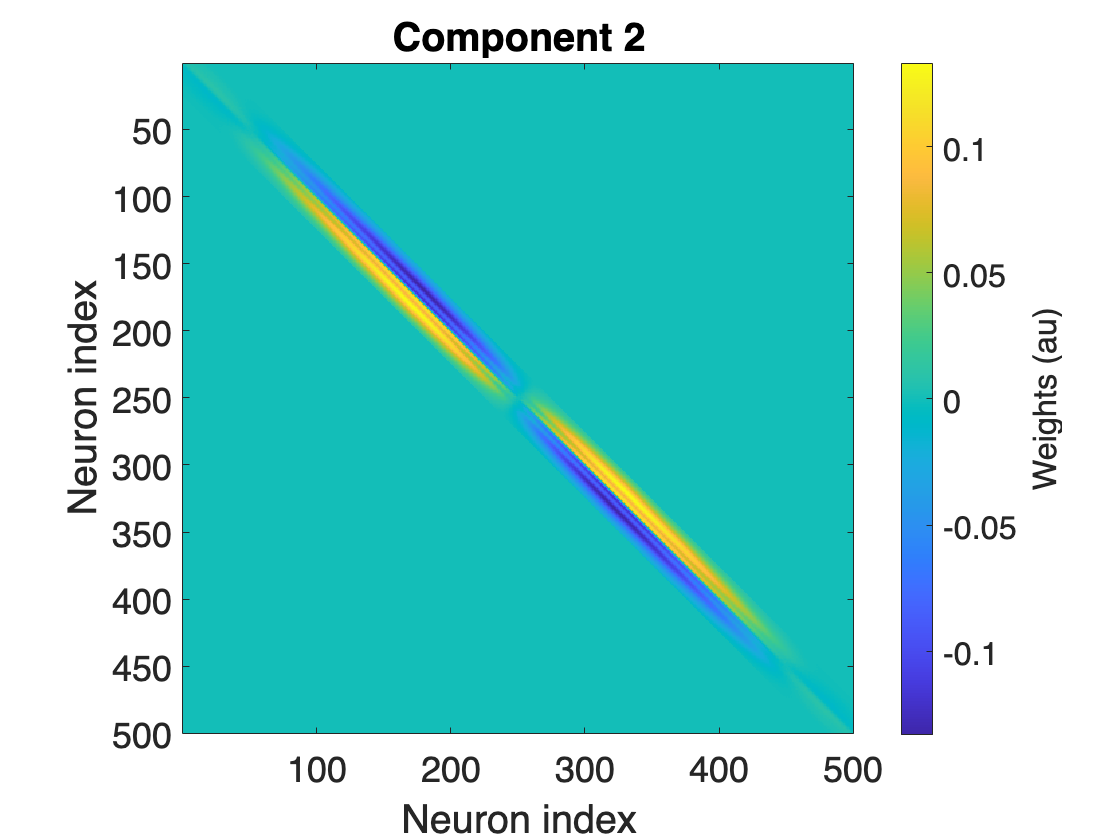

% Plot Component 2
f = figure;
imagesc(PE.pca.s(:,:,2));
a = gca;
a.XLabel.String = 'Neuron index';
a.YLabel.String = 'Neuron index';
a.FontSize = 18; 
axis square; 
cb = colorbar; 
cb.Label.String = 'Weights (au)';
a.Title.String = 'Component 2';

## 2D PCA-space validation

The goal is to compare the empirical matrix trehsolds from STDP_1 to those reconstructed from *only* the first two PCA components in STDP_recon_validation

### Extract validation threshold data for comparison

% Preliminaries
ValidationVarDir = 'ThresholdExperiment/STDP_recon_validation';

% List of all ThresholdExperiments for PlastcitiyExperiment STDP data
ExpNames = dir([ThresholdExperiment('').param.vardir,ValidationVarDir]);
ExpNames = ExpNames(arrayfun(@(f)contains(f.name,'PlasticityExperiment-naive'),ExpNames));

% Sort in numerical order (c.f. character/alphabetical order)
[ExpNums,idx] = sort(arrayfun(@(s)str2num(s.name(28:end)),ExpNames));
ExpNames = ExpNames(idx);

% Create array of ThresholdExperiments
VE = arrayfun(@(f)ThresholdExperiment(f.name),ExpNames);
arrayfun(@(ve)ve.UpdateDir(ValidationVarDir),VE);

% Load and trim array (keep experiments with >0 Simulations)
arrayfun(@(te)Load(te),VE);
idx = arrayfun(@(ve)~isempty(ve.S),VE);
VE = VE(idx);
ExpNums = ExpNums(idx);

% Extract thresholds from both validation simulations and their full
% comparitors
thresholds_validation = arrayfun(@(ve)Threshold(ve),VE);
thresholds_full = arrayfun(@(ve)thresholds(arrayfun(@(te)strcmp(te.param(1).name,ve.param(1).name),TE)),VE);


### Plot validation threshold data against original threshold data

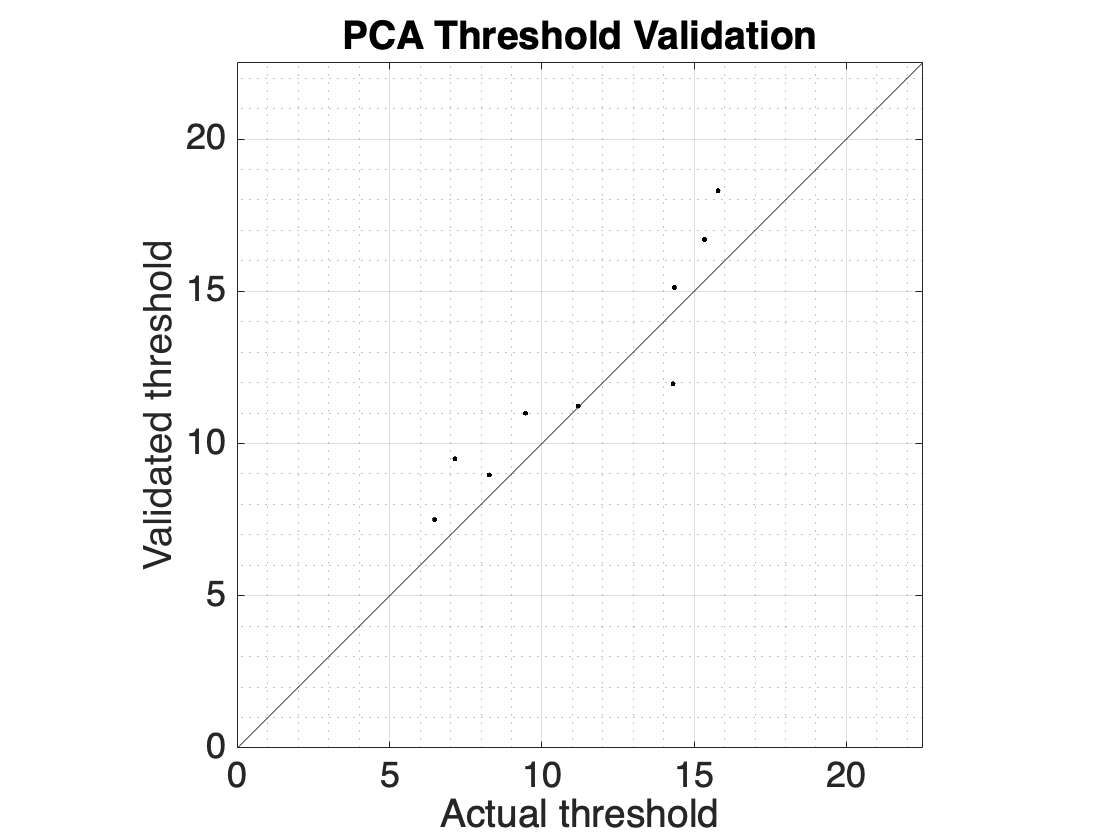

f = figure;
plot(thresholds_full,thresholds_validation,'k.');
hold on;
plot([0 30],[0 30],'k-')
a = gca;
grid on
grid('minor')
axis square
ylim([0 22.5]);
xlim([0 22.5]);
title('PCA Threshold Validation');
xlabel('Actual threshold')
ylabel('Validated threshold');
a.FontSize = 18; axis square;

### Compute $R^2
$ value for unity line

model = fitlm(thresholds_full,thresholds_validation,'linear','Intercept',false)

model = Linear regression model:
    y ~ x1

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    x1     1.0651     0.042558    25.027    6.9528e-09


Number of observations: 9, Error degrees of freedom: 8
Root Mean Squared Error: 1.52

R2 = model.Rsquared

R2 = struct with fields:
    Ordinary: 0.8302
    Adjusted: 0.8302


CI = coefCI(model)

CI =     0.9669    1.1632
